概要

・EMCL占有率等の推定精度についての周波数特性を始めとする種々の周波数特性を調べる．

・TOFpicker(threshold法)のキャリブレーションを各周波数について行う．

・いずれは１：自動でキャリブレーションをするような関数を作成する．

 もしくは２：他の波形先頭抽出法を考える必要がありそう．

１：キャリブレーション(frq1000)

cd '\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_11_no_object_variousFrequency\freq1000'
load rfdata.mat
load kgrid.mat
load sourse_wave.mat

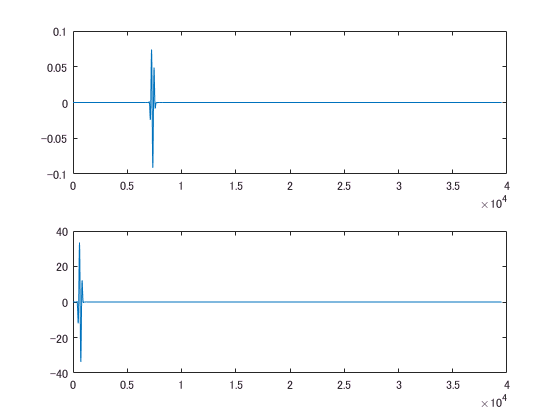

figure;
subplot(2,1,1)
plot(rfdata(:,101));
subplot(2,1,2)
plot(source_wave)

tof_map = threshold_picker(rfdata,kgrid,1000);
v_cal_no_object = 40e-03/tof_map(101,1)

v_cal_no_object = 1.5799e+03

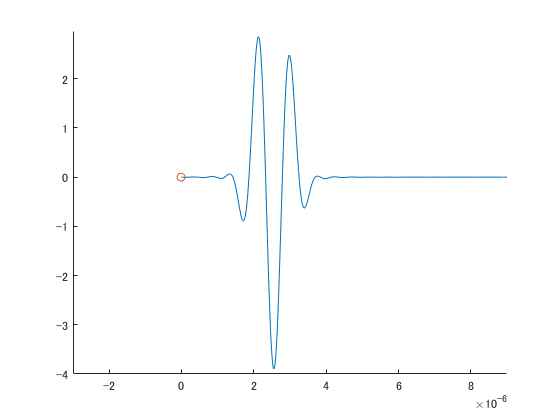

figure;
hold on
plot(kgrid.t_array(1,:),rfdata(:,1));
scatter(tof_map(1,1),0);
xlim([-0.000003 0.000009])
ylim([-4.00 2.97])

２：キャリブレーション(frq500)

cd '\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_11_no_object_variousFrequency\freq500'
load rfdata.mat
load kgrid.mat
load sourse_wave.mat

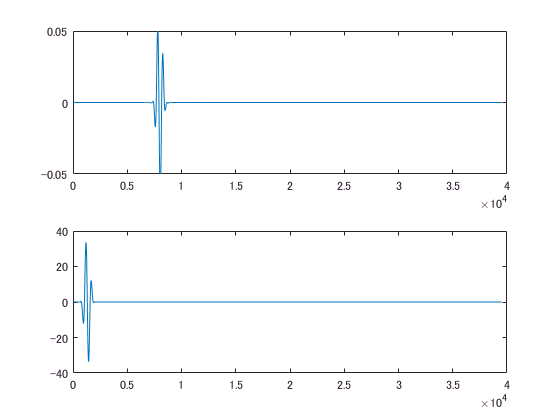

figure;
subplot(2,1,1)
plot(rfdata(:,101));
subplot(2,1,2)
plot(source_wave)
subplot(2,1,1)
xlim([0 40000])
ylim([-0.050 0.050])

tof_map = threshold_picker(rfdata,kgrid,500);
v_cal_no_object = 40e-03/tof_map(101,1)

v_cal_no_object = 1.5799e+03

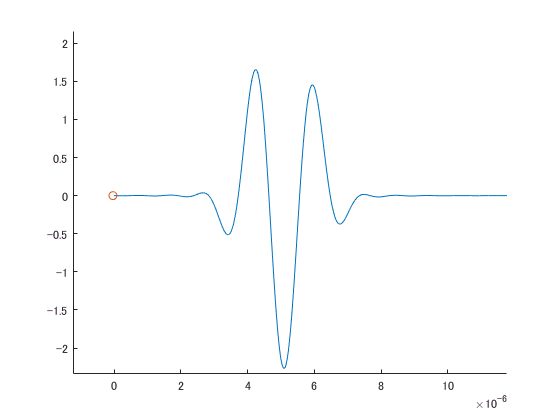

figure;
hold on
plot(kgrid.t_array(1,:),rfdata(:,1));
scatter(tof_map(1,1),0);
xlim([-0.00000123 0.00001177])
ylim([-2.34 2.16])

３：キャリブレーション(frq200)

cd '\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_11_no_object_variousFrequency\freq200'
load rfdata.mat
load kgrid.mat
load sourse_wave.mat

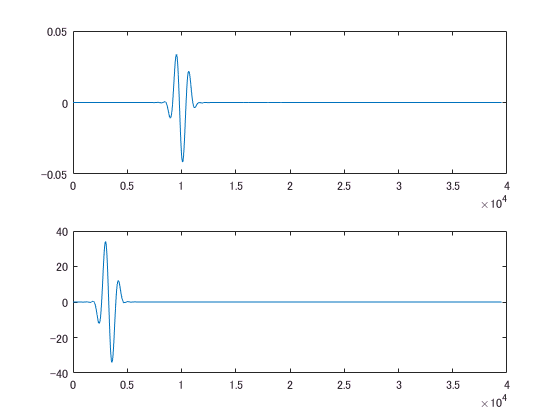

figure;
subplot(2,1,1)
plot(rfdata(:,101));
subplot(2,1,2)
plot(source_wave)
subplot(2,1,1)
xlim([0 40000])
ylim([-0.050 0.050])

tof_map = threshold_picker(rfdata,kgrid,200);
v_cal_no_object = 40e-03/tof_map(101,1)

v_cal_no_object = 1.5799e+03

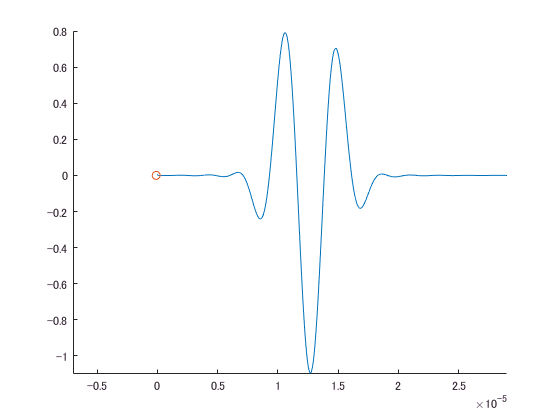

figure;
hold on
plot(kgrid.t_array(1,:),rfdata(:,1));
scatter(tof_map(1,1),0);
xlim([-0.000007 0.000029])
ylim([-1.10 0.80])

４：キャリブレーション(frq100)

cd '\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_11_no_object_variousFrequency\freq100'
load rfdata.mat
load kgrid.mat
load sourse_wave.mat

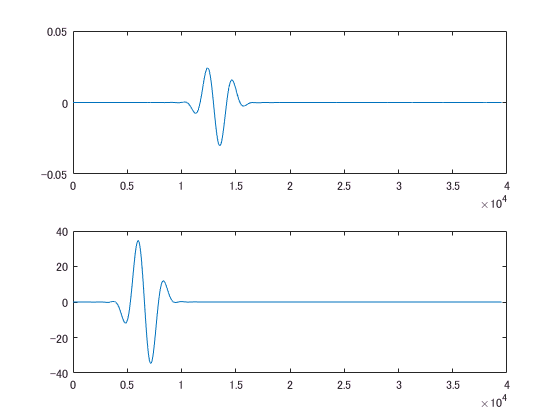

figure;
subplot(2,1,1)
plot(rfdata(:,101));
subplot(2,1,2)
plot(source_wave)
subplot(2,1,1)
xlim([0 40000])
ylim([-0.050 0.050])

tof_map = threshold_picker(rfdata,kgrid,100);
v_cal_no_object = 40e-03/tof_map(101,1)

v_cal_no_object = 1.5799e+03

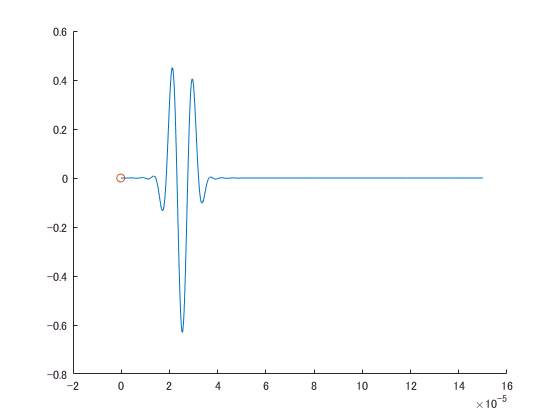

figure;
hold on
plot(kgrid.t_array(1,:),rfdata(:,1));
scatter(tof_map(1,1),0);

５：キャリブレーション(frq50)

cd '\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_11_no_object_variousFrequency\freq50'
load rfdata.mat
load kgrid.mat
load sourse_wave.mat

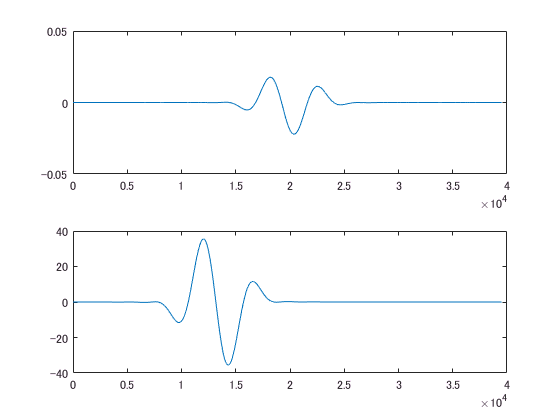

figure;
subplot(2,1,1)
plot(rfdata(:,101));
subplot(2,1,2)
plot(source_wave)
subplot(2,1,1)
xlim([0 40000])
ylim([-0.050 0.050])

tof_map = threshold_picker(rfdata,kgrid,50);
v_cal_no_object = 40e-03/tof_map(101,1)

v_cal_no_object = 1.5799e+03

tof_map(101,1)

ans = 2.5318e-05

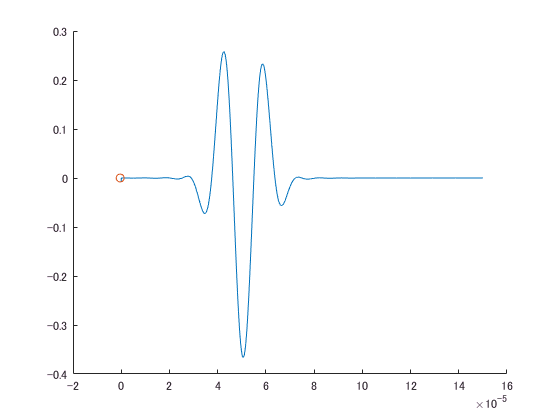

figure;
hold on
plot(kgrid.t_array(1,:),rfdata(:,1));
scatter(tof_map(1,1),0);

6:キャリブレーションの結果，ところどころtofの値が負になっている．

原因をさぐる．\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_08_variousFrequency\case25_Freq50

のrfデータを用いて，波形先頭抽出の様子を可視化する．

load('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_08_variousFrequency\case25_Freq50\rfdata.mat')
load('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_08_variousFrequency\case25_Freq50\kgrid.mat')

load('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_08_variousFrequency\tof_cell.mat')
load('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_08_variousFrequency\case25_Freq50\sourse_wave.mat')

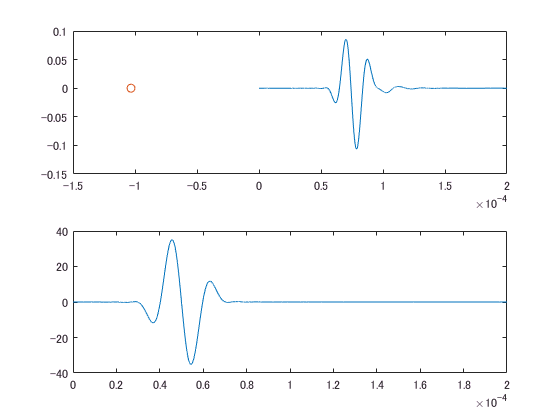

a = length(rfdata);
figure;
subplot(2,1,1)
plot(kgrid.t_array(1,:),rfdata(:,101,1));
hold on
scatter(tof_cell(101,1,25,5),0);
subplot(2,1,2)
plot(kgrid.t_array(1,:),source_wave)

明らかにキャリブレーションができていない．どこかコンフィグレーションの段階でミスをしている．

ここでわかったこととしては，低周波数だと構造からの影響によって速度分散が大きくなることはあまりない，ということである．

分散性について議論するためには，リファレンス波との相互相関をとって評価することが有用でありそうだ．

７：キャリブレーション時のkgrid.dtもしくはサンプリング数と，多様な媒質でシミュレーションを行ったときのサンプリング数が一致しているか確認する．

load('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_08_variousFrequency\case25_Freq50\kgrid.mat')
comp1 = kgrid.Nt

comp1 = 10534

comp1_1 = kgrid.Nx

comp1_1 = 500

load('\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_11_no_object_variousFrequency\freq50\kgrid.mat')
comp0 = kgrid.Nt

comp0 = 39501

comp0_1 = kgrid.Nx

comp0_1 = 2500

一致していなかった．なぜ．

comp0/comp1

ans = 3.7499

結論：誤ってmedium/2018_08_23_no_object_largeを使用してしまった．計算グリッドサイズが25倍小さな媒質でバリデーションをしてしまっていた．

８：キャリブレーションを再試行する．

frq = 1000

cd '\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_11_no_object_variousFrequency\freq1000_valid'
load rfdata.mat
load kgrid.mat
load sourse_wave.mat

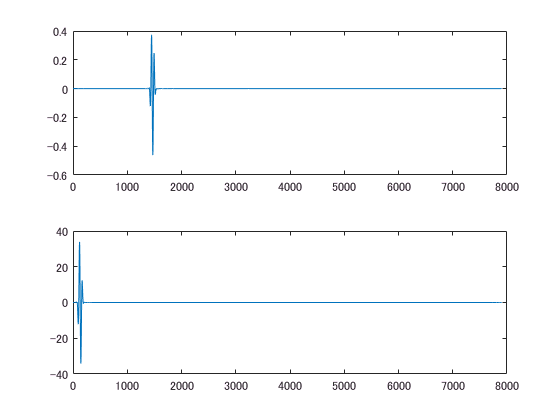

figure;
subplot(2,1,1)
plot(rfdata(:,101));
subplot(2,1,2)
plot(source_wave)

tof_map = threshold_picker(rfdata,kgrid,1000);
v_cal_no_object = 40e-03/tof_map(101,1)

v_cal_no_object = 1.5800e+03

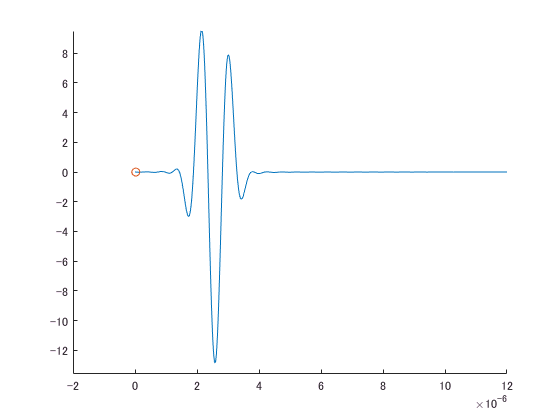

    figure;
hold on
plot(kgrid.t_array(1,:),rfdata(:,1));
scatter(tof_map(1,1),0);
xlim([-0.000002 0.000012])
ylim([-13.6 9.5])

９：frq = 500

cd '\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_11_no_object_variousFrequency\freq500_valid'
load rfdata.mat
load kgrid.mat
load sourse_wave.mat

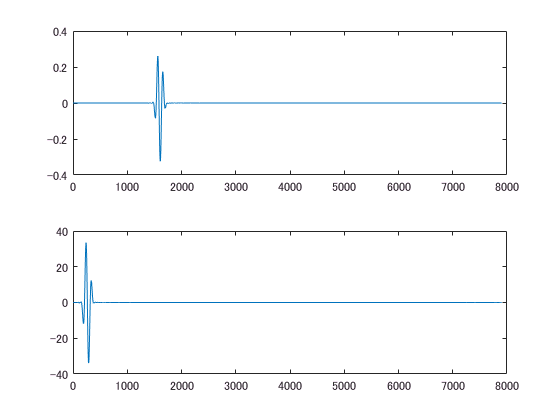

figure;
subplot(2,1,1)
plot(rfdata(:,101));
subplot(2,1,2)
plot(source_wave)

tof_map = threshold_picker(rfdata,kgrid,500);
v_cal_no_object = 40e-03/tof_map(101,1)

v_cal_no_object = 1.5780e+03

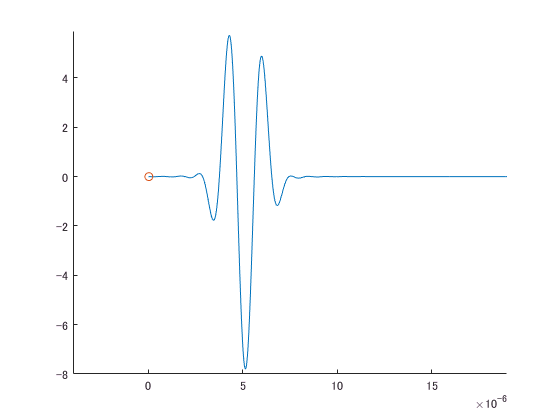

figure;
hold on
plot(kgrid.t_array(1,:),rfdata(:,1));
scatter(tof_map(1,1),0);
xlim([-0.000004 0.000019])
ylim([-8.0 5.9])

１０：frq = 200

cd '\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_11_no_object_variousFrequency\freq200_valid'
load rfdata.mat
load kgrid.mat
load sourse_wave.mat

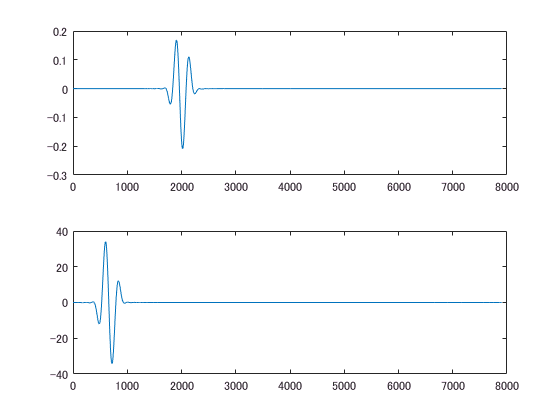

figure;
subplot(2,1,1)
plot(rfdata(:,101));
subplot(2,1,2)
plot(source_wave)
subplot(2,1,1)

tof_map = threshold_picker(rfdata,kgrid,200);
v_cal_no_object = 40e-03/tof_map(101,1)

v_cal_no_object = 1.5800e+03

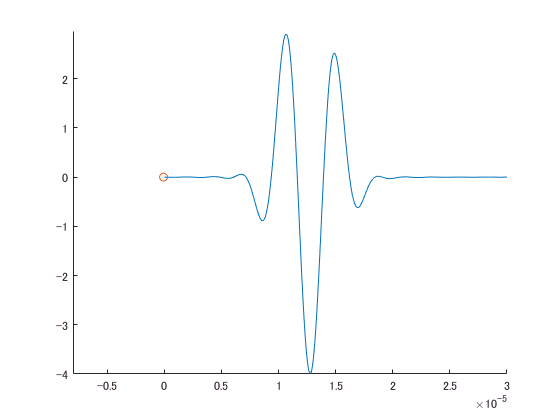

figure;
hold on
plot(kgrid.t_array(1,:),rfdata(:,1));
scatter(tof_map(1,1),0);
xlim([-0.000008 0.000030])
ylim([-4.00 2.97])

１１：frq=100

cd '\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_11_no_object_variousFrequency\freq100_valid'
load rfdata.mat
load kgrid.mat
load sourse_wave.mat

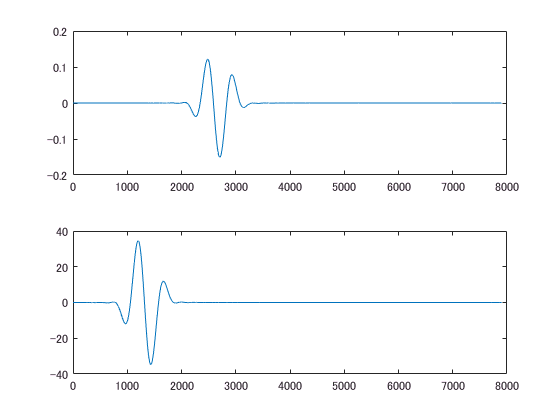

figure;
subplot(2,1,1)
plot(rfdata(:,101));
subplot(2,1,2)
plot(source_wave)
subplot(2,1,1)

tof_map = threshold_picker(rfdata,kgrid,100);
v_cal_no_object = 40e-03/tof_map(101,1)

v_cal_no_object = 1580

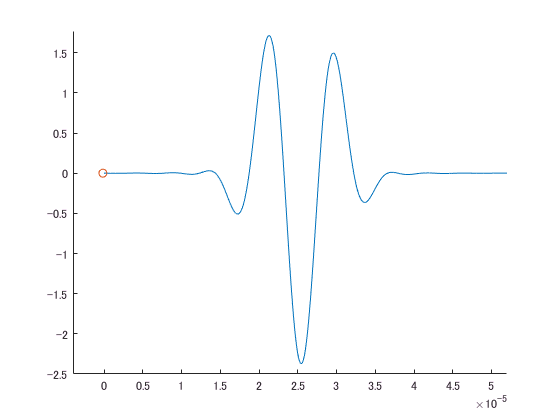

figure;
hold on
plot(kgrid.t_array(1,:),rfdata(:,1));
scatter(tof_map(1,1),0);
xlim([-0.000004 0.000052])
ylim([-2.50 1.77])

１２：frq=50

cd '\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_11_no_object_variousFrequency\freq50_valid'
load rfdata.mat
load kgrid.mat
load sourse_wave.mat

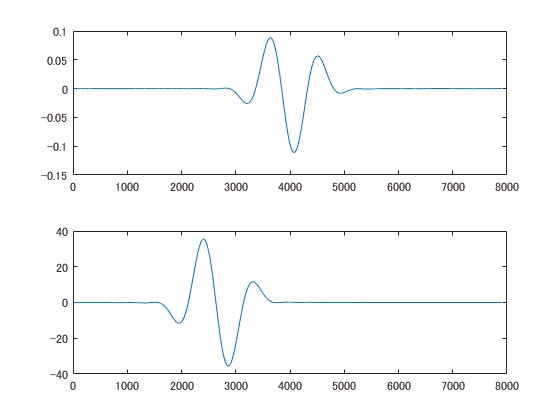

figure;
subplot(2,1,1)
plot(rfdata(:,101));
subplot(2,1,2)
plot(source_wave)
subplot(2,1,1)

tof_map = threshold_picker(rfdata,kgrid,50);
v_cal_no_object = 40e-03/tof_map(101,1)

v_cal_no_object = 1.5800e+03

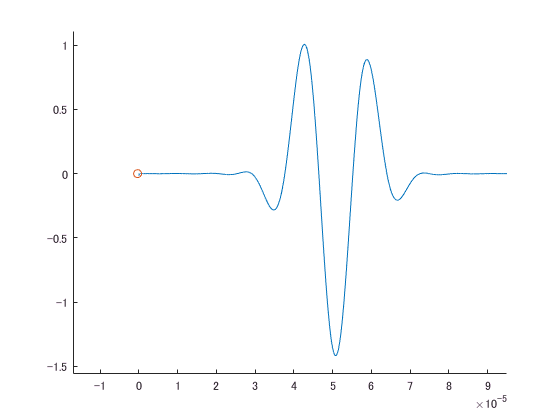

figure;
hold on
plot(kgrid.t_array(1,:),rfdata(:,1));
scatter(tof_map(1,1),0);
xlim([-0.000017 0.000095])
ylim([-1.56 1.11])

１３：平均音速値を全組み合わせ6(周波数) x 25（媒質数）でプロットすると，frq = 50のものだけが外れ値を出した．

周波数が低くなるに連れて平均音速が微かに下がる傾向であったものが，ジャンプを起こしてしまっている．

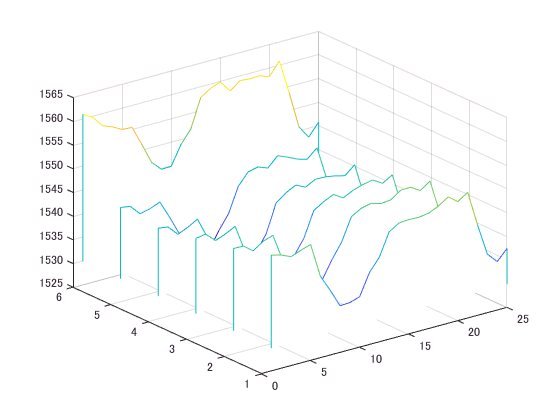

cd \\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_08_variousFrequency
load statistics.mat
figure;
waterfall(aveSOS2);

１４：これは現象に沿った，正しい結果なのかを上述のバリデーション手順を流用して確認する．

cd '\\Azlab-fs01\東研究室\個人work\竹内(ひ)\data\kwave\result\2018_09_08_variousFrequency\case1_freq50'
load rfdata.mat
load kgrid.mat
load sourse_wave.mat

tof_map = threshold_picker(rfdata,kgrid,50);
v_cal_no_object = 40e-03/tof_map(150,50)

v_cal_no_object = 1.5532e+03

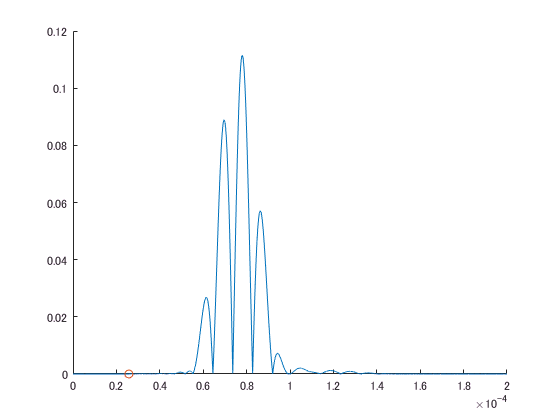

figure;
hold on
plot(kgrid.t_array(1,:),abs(rfdata(:,150,50)));
scatter(tof_map(150,50),0);

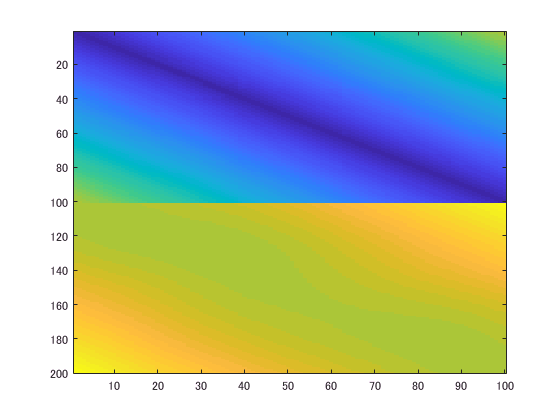

figure;imagesc(tof_map);

特に大きな拾い忘れはないようだ．

周波数と波形歪みの関係を調べるとなにか分かりそうだ．